# Correlation between mortality and median age in Switzerland from 1960 to 2020

## Import death data from spreadsheet

opts = spreadsheetImportOptions("NumVariables", 14);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A3:N62";

% Specify column names and types
opts.VariableNames = ["Year", "Total", "January", "February", "March", "April", "May", "June", "July", "August", "September", "October", "November", "December"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
myDeath = readtable("Deaths_in_Switzerland.xlsx", opts, "UseExcel", false)

myDeath = 60×14 table
    Year    Total    January    February    March    April    May     June    July    August    September    October    November    December
    ____    _____    _______    ________    _____    _____    ____    ____    ____    ______    _________    _______    ________    ________

    1960    52094     5291        5874      4437     4102     4154    3683    3792     3780       3819        4294        4167        4701  
    1961    51004     4751        4252      4431     4094     4211    4082    

clear opts

## Import age data from spreadsheet

opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:B62";

% Specify column names and types
opts.VariableNames = ["Year", "MedianAge"];
opts.VariableTypes = ["double", "double"];

% Import the data
myAge = readtable("Age_in_Switzerland.xlsx", opts, "UseExcel", false)

myAge = 61×2 table
    Year    MedianAge
    ____    _________

    2020       43.1  
    2019      42.36  
    2018      42.36  
    2017      42.36  
    2016      42.36  
    2015      42.36  
    2014       41.6  
    2013       41.6  
    2012       41.6  
    2011       41.6  
    2010       41.6  
    2009         40  
    2008         40  
    2007         40  
    2006         40  
    2005         40  


clear opts

## Store data in a usable format

% Format data on mortality
myDeath = table2array(myDeath);

death_years = myDeath(:,1);
total_deaths = myDeath(:,2);
myDeath = myDeath(:, 3:end);

% Format data on age
myAge = table2array(myAge);

age_years = myAge(end:-1:1, 1);
median_age = myAge(end:-1:1, 2);

## Inspect the variables with respect to time

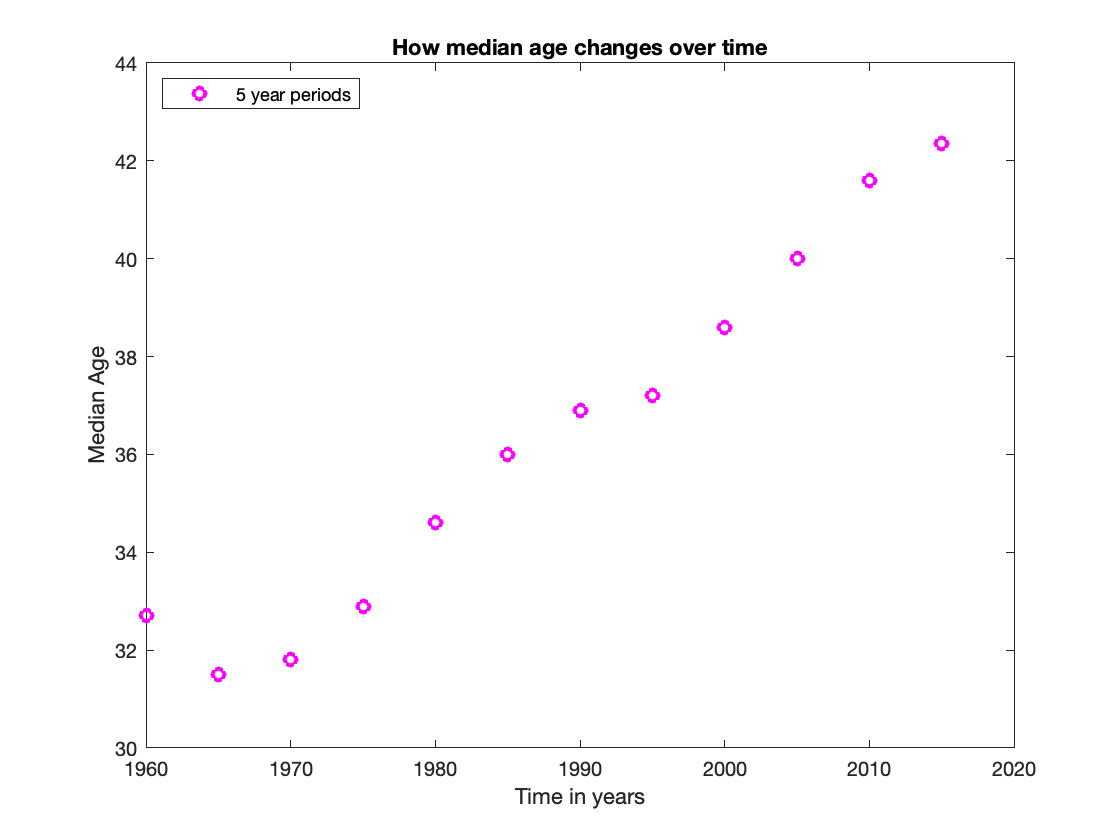

plot(age_years(1:5:end - 1), median_age(1:5:end - 1), 'mo', 'LineWidth', 2)
hold on

xlabel('Time in years')
ylabel('Median Age')

title('How median age changes over time')
legend('5 year periods', 'Location', 'northwest')
hold off

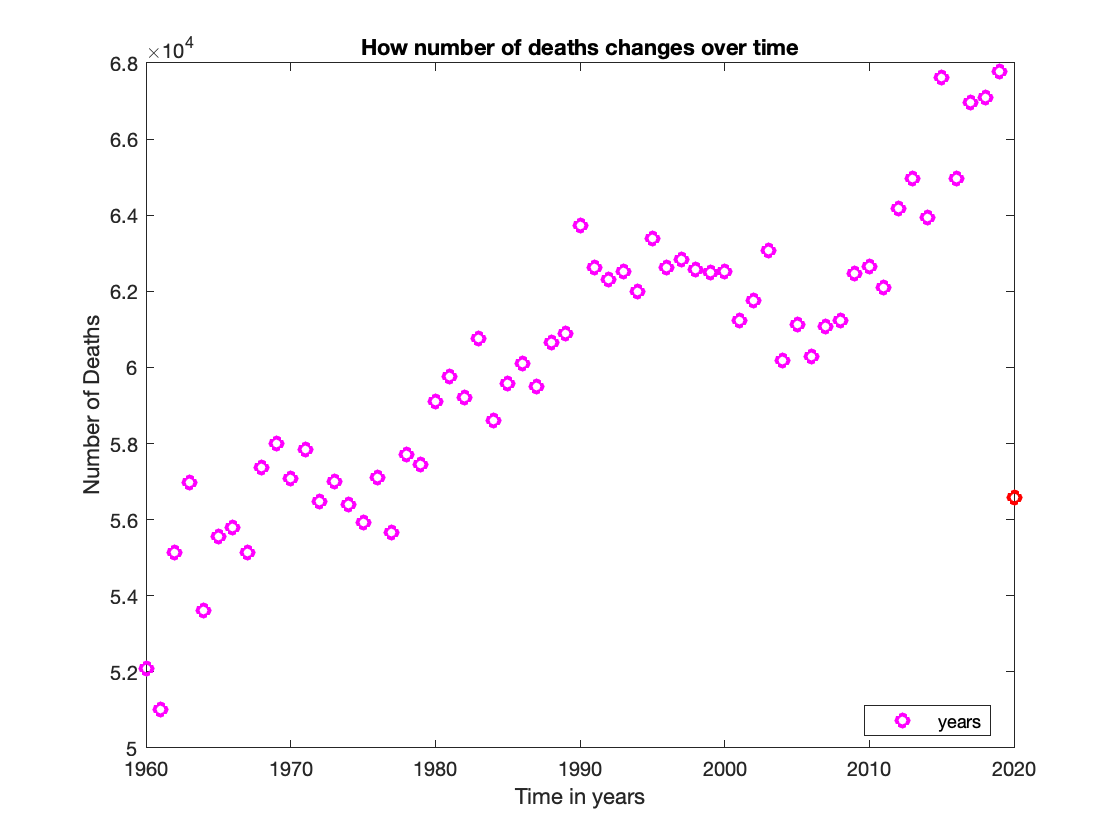


plot(death_years, total_deaths, 'mo', 'LineWidth', 2)
hold on

plot(age_years(end), predicted_death, 'ro', 'LineWidth', 2)

xlabel('Time in years')
ylabel('Number of Deaths')

title('How number of deaths changes over time')
legend('years', 'Location', 'best')
hold off

## Analyse correlation between mortality and median age

%%% grouping total deaths into 5 year periods

group_number = round(length(total_deaths)/ 5);
grouped_deaths = zeros(12, 1);

for i = 1:group_number
    
    grouped_deaths(i) = mean(total_deaths(i:i + 4));
    % grouped_deaths(i) = sum(total_deaths(i:i + 4));
    
end

%%% linear model

linear_model = fitlm(median_age(1:5:end - 1), grouped_deaths);

formula = linear_model.Formula

formula = y ~ 1 + x1

Rsquare = linear_model.Rsquared

Rsquare = struct with fields:
    Ordinary: 0.6714
    Adjusted: 0.6385


plot(median_age(1:5:end - 1), grouped_deaths, 'o')
hold on

f1 = fit(median_age(1:5:end - 1), grouped_deaths, 'm*x+b')

f1 =      General model:
     f1(x) = m*x+b
     Coefficients (with 95% confidence bounds):
       b =   4.684e+04  (4.226e+04, 5.142e+04)
       m =       254.4  (129, 379.8)

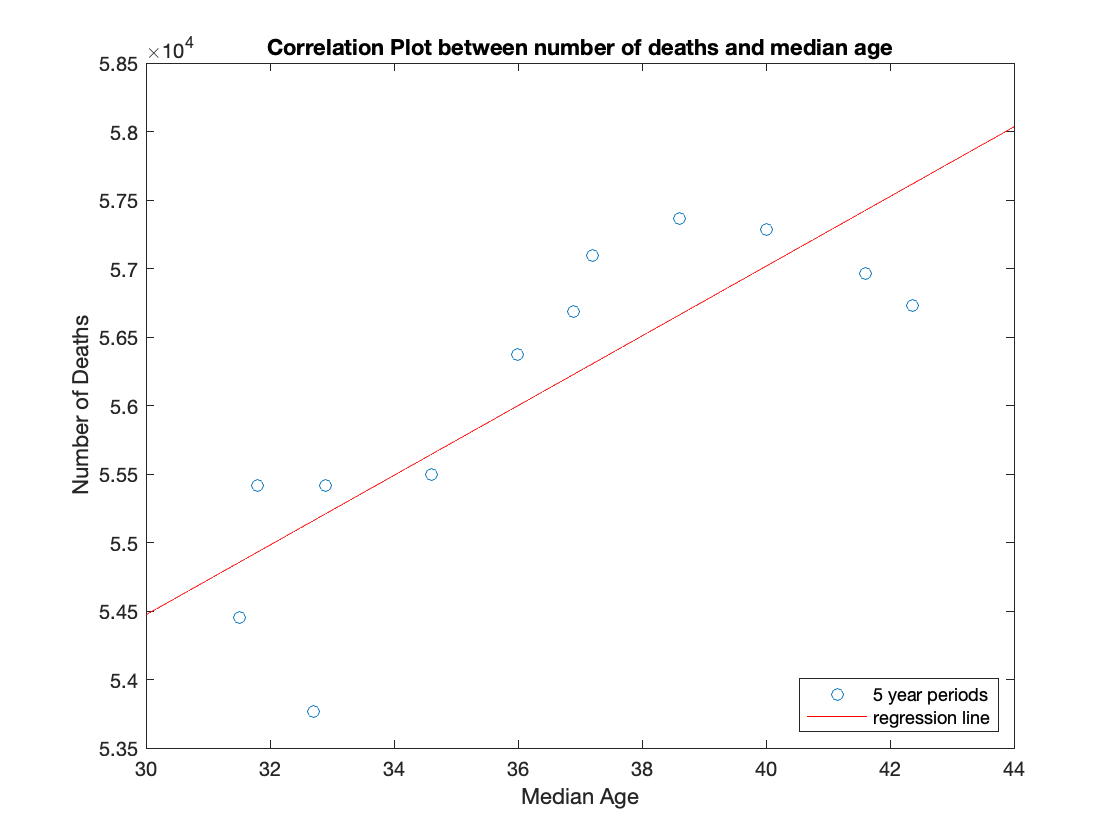

plot(f1, 'r')

title('Correlation Plot between number of deaths and median age')

xlabel('Median Age')
ylabel('Number of Deaths')

legend('5 year periods', 'regression line', 'Location', 'southeast')
hold off


CI = confint(f1);
display(['slope_uncertainty: ', num2str((CI(2,1) - CI(1,1)) / 2)])

slope_uncertainty: 4580.0723


display(['intercept_uncertainty: ', num2str((CI(2,2) - CI(1,2)) / 2)])

intercept_uncertainty: 125.3964


## Focus on the most recent years

If the focus is drawn onto a shorter timelapse, then a temporary correlation could be identified between the two variables.

It is possible to relate the number of deaths to the median age in a linear fashion for the last two 5 year periods (2010 - 2014 and 2015 - 2019), from which the numbers for the following period (2020 - 2024) could be deduced.

groups_back = 2;
years_back = 5 * groups_back + 5;

tSpan = age_years(end - years_back:end - 1);
myMedianAge = median_age(end - years_back:5:end - 1);
myGroupedDeaths = grouped_deaths(end - groups_back:end);

plot(myMedianAge, myGroupedDeaths, 'o')
hold on

f2 = fit(myMedianAge, myGroupedDeaths, 'm*x+b')

f2 =      General model:
     f2(x) = m*x+b
     Coefficients (with 95% confidence bounds):
       b =   6.646e+04  (5.284e+04, 8.008e+04)
       m =      -229.1  (-558.6, 100.5)

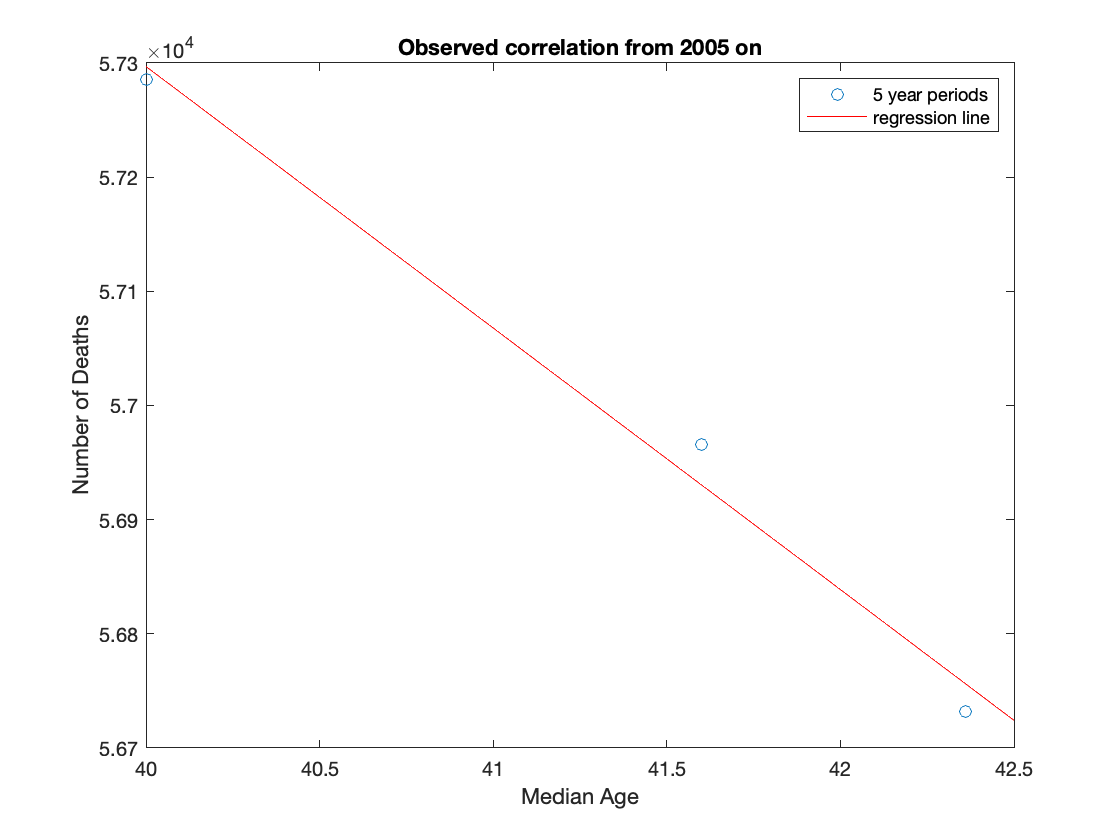

plot(f2, 'r')

title(['Observed correlation from ', num2str(tSpan(1)), ' on'])

xlabel('Median Age')
ylabel('Number of Deaths')

legend('5 year periods', 'regression line', 'Location', 'northeast')
hold off


CI = confint(f2);
display(['slope_uncertainty: ', num2str((CI(2,1) - CI(1,1)) / 2)])

slope_uncertainty: 13621.7356


display(['intercept_uncertainty: ', num2str((CI(2,2) - CI(1,2)) / 2)])

intercept_uncertainty: 329.5711


## Prediction of mortality in 2020

rough_predicted_death = f2.m * median_age(end) + f2.b;
predicted_death = rough_predicted_death

predicted_death = 5.6587e+04